# Training Yolo V4 object detector for Cuboid objects for simulation 

This script is an example of how to train YOLOv4 detector for cuboid objects

rng('default');

%parameters
doAugmentation = true;

#### Create Training data from the labeled dataset

datasetFolder1 = 'dataset_1'; % provide path to your dataset here
real1_ds = load(fullfile(datasetFolder1,'gTruth.mat'));
trainingDataset1 = objectDetectorTrainingData(real1_ds.gTruth);

% for dataset in multiple folders repeat the above steps
datasetFolder1 = 'dataset_2';
real1_ds = load(fullfile(datasetFolder1,'gTruth.mat'));
trainingDataset2 = objectDetectorTrainingData(real1_ds.gTruth);

datasetFolder1 = 'dataset_3';
real1_ds = load(fullfile(datasetFolder1,'gTruth.mat'));
trainingDataset3 = objectDetectorTrainingData(real1_ds.gTruth);

datasetFolder1 = 'dataset_4';
real1_ds = load(fullfile(datasetFolder1,'gTruth.mat'));
trainingDataset4 = objectDetectorTrainingData(real1_ds.gTruth);


%Combine all datasets
trainingDataset_real = vertcat(trainingDataset1,trainingDataset2,trainingDataset3,trainingDataset4);

#### Divide the dataset for training and testing

% for reproducible
rng(0);

trainingDataset = trainingDataset_real;
shuffledIndices = randperm(height(trainingDataset));
idx = floor(0.9 * length(shuffledIndices) );
trainingDataTbl = trainingDataset(shuffledIndices(1:idx),:);
testDataTbl = trainingDataset(shuffledIndices(idx+1:end),:);

% Use |imageDatastore| and |boxLabelDatastore| to create datastores for loading
% the image and label data during training and evaluation.

imdsTrain = imageDatastore(replace(string(trainingDataTbl{:,'imageFilename'}),'\',filesep));
bldsTrain = boxLabelDatastore(trainingDataTbl(:,2:end));

imdsTest = imageDatastore(replace(string(testDataTbl{:,'imageFilename'}),'\',filesep));
bldsTest = boxLabelDatastore(testDataTbl(:,2:end));

% Combine image and box label datastores.

trainingData = combine(imdsTrain,bldsTrain);
testData = combine(imdsTest,bldsTest);

#### Visualize a sample from the labeled data

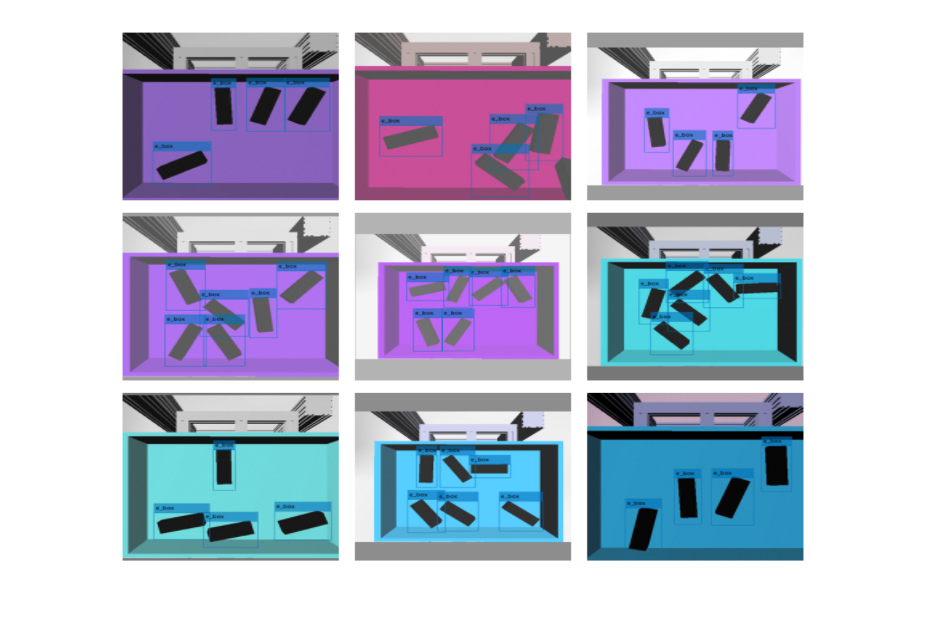

trainingData.reset;
data = read(trainingData);
I = data{1};
bboxes = data{2};
labels = data{3};

classNames = trainingDataset_real.Properties.VariableNames(2:end);
cmaps = im2uint8(lines(numel(classNames)));

labels = categorical(labels,classNames);
annotatedImage = insertObjectAnnotation(I, 'Rectangle', bboxes, cellstr(labels),...
    'Color',cmaps(int32(labels),:));

figure
imshow(annotatedImage)

## Define the YOLOv4 network for training 

detector = yolov4ObjectDetector('tiny-yolov4-coco');

## Data Augmentation and Preprocess Data

Data augmentation is used to improve network accuracy by randomly transforming

the original data during training. By using data augmentation, you can add more

variety to the training data without actually having to increase the number

of labeled training samples.

networkInputSize = detector.InputSize;
preprocessedTrainingData = transform(trainingData, @(x)augmentDataKeepingAspectRatio(x,networkInputSize,doAugmentation));
reset(preprocessedTrainingData);

% modify the network
lGraph = layerGraph(detector.Network);
baseNetwork = dlnetwork(lGraph);
anchorBoxes = detector.AnchorBoxes;
detector = yolov4ObjectDetector(baseNetwork, classNames,...
    anchorBoxes, 'DetectionNetworkSource', detector.Network.OutputNames);

## Visualize augmented and preprocessed image samples.

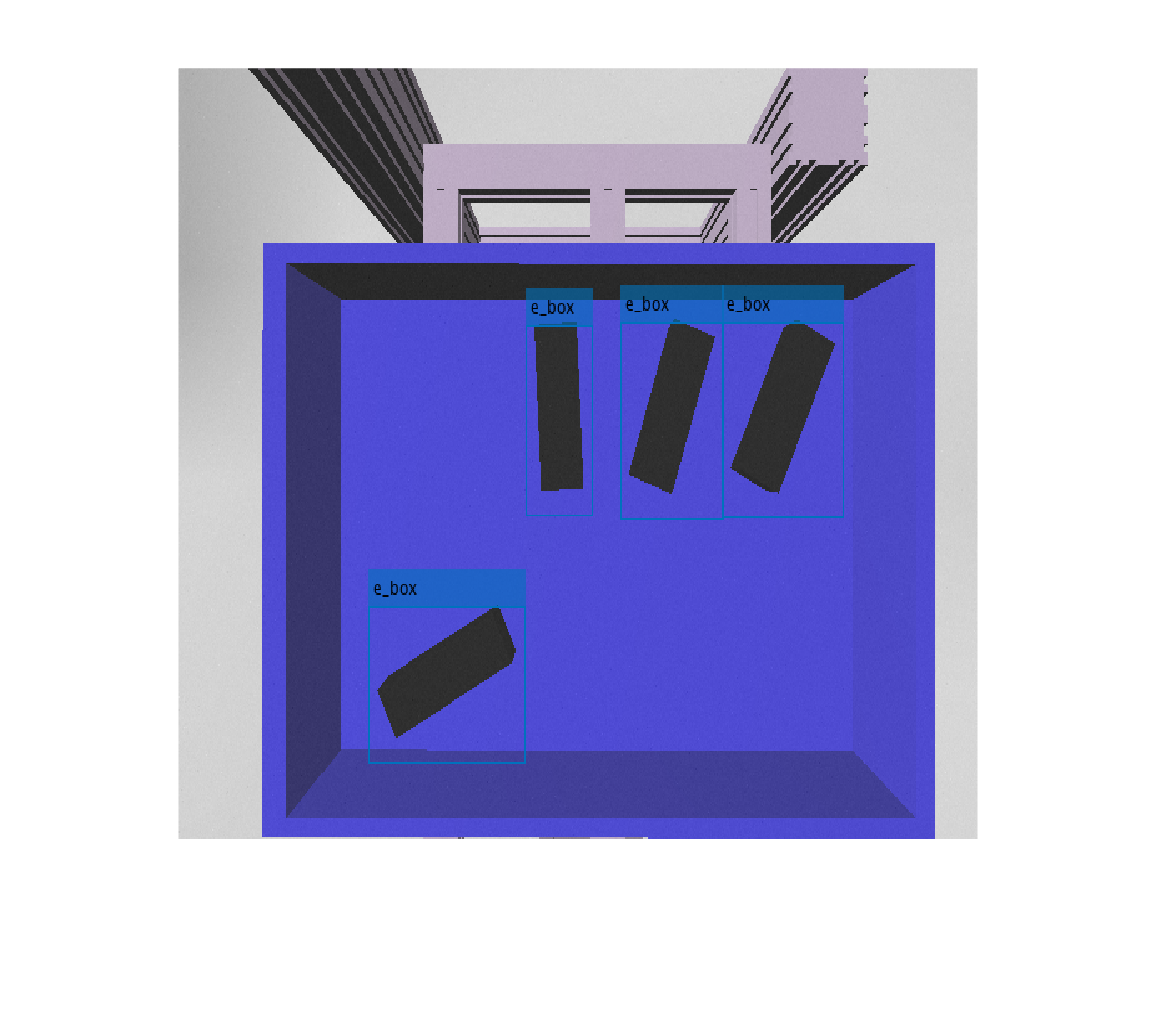

augmentedData = cell(9,1);
numClasses = numel(classNames);
rng('default');
for k = 1:9
    data = read(preprocessedTrainingData);
    [~,loc] = ismember(data{1,3},classNames');
    augmentedData{k} = insertObjectAnnotation(im2uint8(data{1,1}), 'Rectangle', data{1,2}, data{1,3},...
        'Color', cmaps(loc,:));
end
figure
montage(augmentedData, 'BorderSize', 10, 'BackgroundColor', 'white',...
    'Interpolation','bilinear')

reset(preprocessedTrainingData);


## Training options for YOLOv4

options = trainingOptions("adam",...
    GradientDecayFactor=0.9,...
    SquaredGradientDecayFactor=0.999,...
    InitialLearnRate=0.001,...
    LearnRateSchedule="piecewise",...
    MiniBatchSize=8,...
    L2Regularization=0.0005,...
    MaxEpochs=8,...
    BatchNormalizationStatistics="moving",...
    DispatchInBackground=false,...
    ResetInputNormalization=false,...
    Shuffle="every-epoch",...
    Verbose=true,...
    LearnRateDropFactor=0.75,...
    ExecutionEnvironment='gpu',... % Update this option to 'gpu' to use GPU for training
    LearnRateDropPeriod=15,...
    VerboseFrequency=10);

## Train YOLOv4 object detector 

t = tic;
[detector,info] = trainYOLOv4ObjectDetector(preprocessedTrainingData,detector,options);

*************************************************************************
Training a YOLO v4 Object Detector for the following object classes:

* e_box

 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingLoss
    _____    _________    ___________    _________    ____________
      1         10         00:00:06        0.001         600.94   
      1         20         00:00:09        0.001         201.25   
      2         30         00:00:14        0.001         106.76   
      2         40         00:00:18        0.001          71.7    
      2         50         00:00:22        0.001         53.674   
      3         60         00:00:26        0.001         46.891   
      3         70         00:00:30        0.001         38.724   
      3         80         00:00:33        0.001         32.752   
     

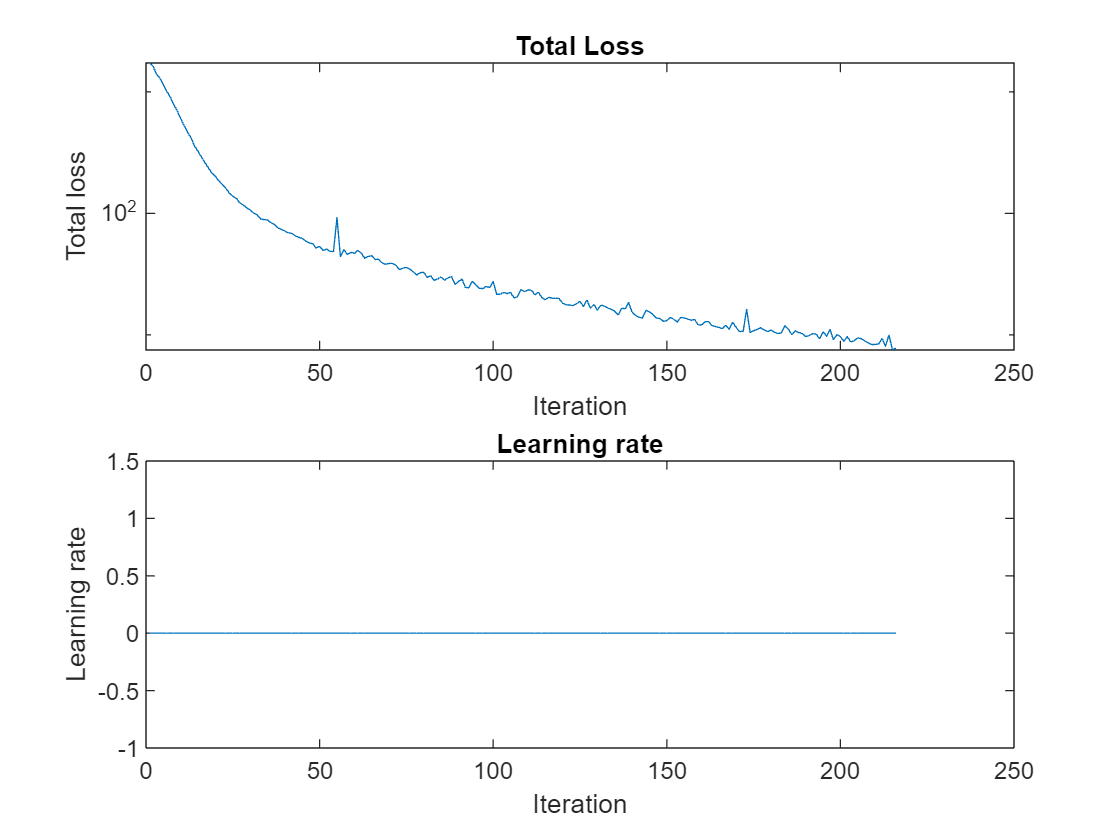

elapsedTime = toc(t);
save(fullfile('trainedYOLOv4DetectorSimGazebo_cuboid'),'detector','info','elapsedTime');

% Vizualize the training loss
figure;
subplot(2,1,1);
semilogy(1:info.OutputNetworkIteration,info.TrainingLoss);
title('Total Loss');
xlabel('Iteration');
ylabel('Total loss');
subplot(2,1,2);
plot(1:info.OutputNetworkIteration,info.BaseLearnRate);
title('Learning rate');
xlabel('Iteration');
ylabel('Learning rate');

## Validate trained YOLOv4 object detector 

reset(testData);
numImages = testData.numpartitions;
disp("The number of test data : " + numImages);

The number of test data : 24


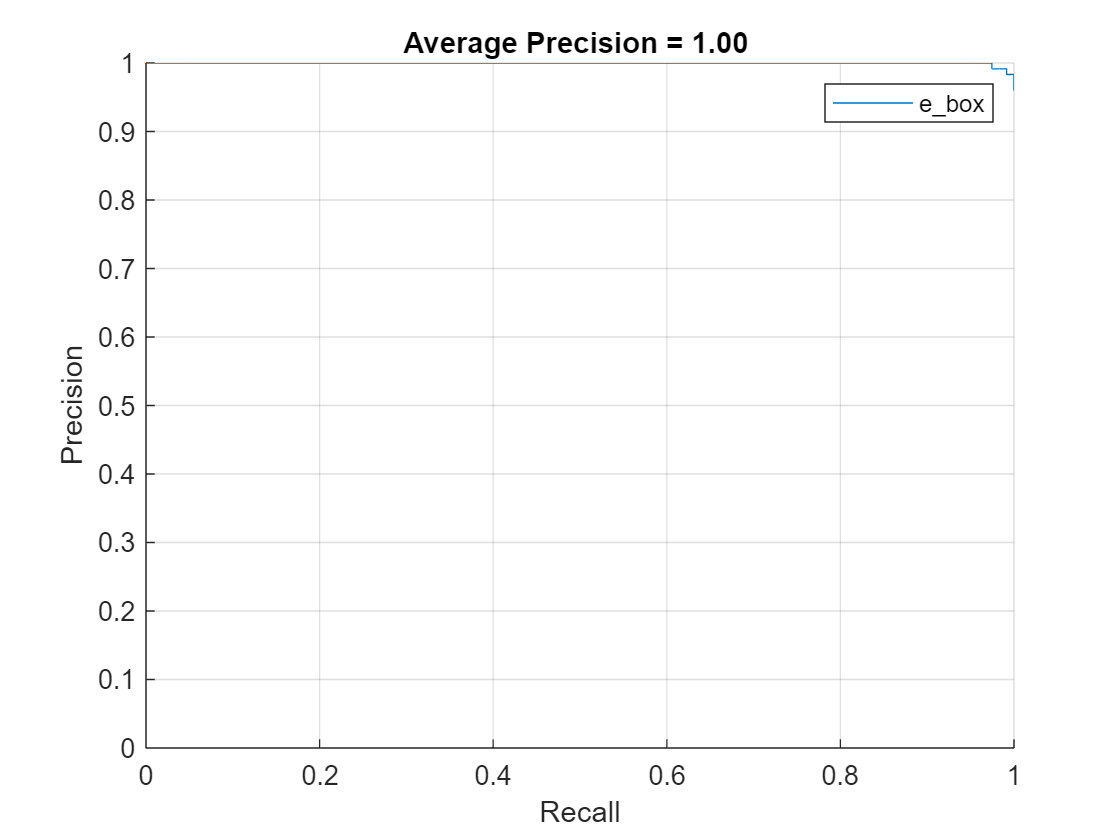

results = table('Size',[numImages 3],...
    'VariableTypes',{'cell','cell','cell'},...
    'VariableNames',{'Boxes','Scores','Labels'  });
reset(testData);
expectedResults = testDataTbl(:, 2:end);

videoPlayer = vision.DeployableVideoPlayer;
for i = 1:numImages

    data = read(testData);
    Iorg = im2uint8(data{1});
    I = imresize(Iorg,[nan,networkInputSize(2)]);
    I = cat(1,I,im2uint8(0.5*ones(networkInputSize(1)-size(I,1),size(I,2),size(I,3))));

    [bboxes,scores,labels] = detect(detector,I);

    topLeft = bboxes(:,1:2) - 1;
    topLeft = topLeft.*(size(Iorg,2)./networkInputSize(2));
    bboxes = [topLeft + 1, bboxes(:,3:4).*(size(Iorg,2)./networkInputSize(2))];

    % convert categorical labels to cell array of character vectors for MATLAB
    % execution
    labels = categorical(labels,classNames);

    % Visualization
    if isempty(labels)
        detectedImg = Iorg;
    else
        detectedImg = insertObjectAnnotation(Iorg, 'Rectangle', bboxes, labels,...
            'Color',cmaps(int32(labels),:));
    end
    videoPlayer(detectedImg);

    results.Boxes{i} = bboxes;
    results.Scores{i} = scores;
    results.Labels{i} = labels;
end

[ap, recall, precision] = evaluateDetectionPrecision(results, expectedResults,0.3);

figure
hold on;
if iscell(recall)
    for k = 1:numel(recall)
        plot(recall{k},precision{k});
    end
else
    plot(recall,precision);
end
xlabel('Recall')
ylabel('Precision')
axis([0 1 0 1]);
grid on
legend(testDataTbl.Properties.VariableNames(2:end),'Interpreter','none');
title(sprintf('Average Precision = %.2f ', mean(ap)))

## Helper functions

function data = augmentDataKeepingAspectRatio(A,inputSize,doAugmentation)
% Data augmentation
% This function helps in increasing the training images by data augmentation
% Scaling and randomly altering color of the pixels are used in this script
targetSize = [inputSize(2),inputSize(1)];
data = cell(size(A));
for ii = 1:size(A,1)
    I = A{ii,1};
    bboxes = A{ii,2};
    labels = A{ii,3};
    sz = size(I);
    if numel(sz) < 3
        I = repmat(I,[1 1 3]);
    end

    if doAugmentation
        zoomRange = [0.8 1.5];
        rotateRange = deg2rad(0);
        translateRange = 0;
        flip = false;
    else
        zoomRange = [1 1];
        rotateRange = 0;
        translateRange = 0;
        flip = false;
    end

    centerXShift = sz(2)/2;
    centerYShift = sz(1)/2;
    [moveToOriginTransform,moveBackTransform] = deal(eye(3));
    moveToOriginTransform(3,1) = -centerXShift;
    moveToOriginTransform(3,2) = -centerYShift;
    moveBackTransform(3,1) = centerXShift;
    moveBackTransform(3,2) = centerYShift;

    zoomFactor = rand(1,1)*(zoomRange(2)-zoomRange(1))+zoomRange(1);
    scaleTransform = [zoomFactor 0 0;
        0 zoomFactor 0;
        0 0 1];

    rotationFactor = randn(1,1)*rotateRange;
    rotationFactor = min(max(rotationFactor,-rotateRange*2),rotateRange*2);
    rotationTransform = [cos(rotationFactor) sin(rotationFactor) 0;
        -sin(rotationFactor) cos(rotationFactor) 0;
        0 0 1];
    if flip && (rand > 0.5)
        x_scale = -1;
    else
        x_scale = 1;
    end
    reflectionTransform = [x_scale 0 0; 0 1 0; 0 0 1];

    translationTransform = eye(3);
    translationTransform(3,1) = randn*translateRange;
    translationTransform(3,2) = randn*translateRange;

    [maxEdge,ind] = max([sz(1),sz(2)]);
    scale = targetSize(ind)/maxEdge;
    scaledTransform = eye(3);
    scaledTransform(1,1) = scale;
    scaledTransform(2,2) = scale;

    moveToTopLeftTransform = eye(3);
    moveToTopLeftTransform(3,1) = (targetSize(2)/scale-sz(2))/2;
    moveToTopLeftTransform(3,2) = (targetSize(1)/scale-sz(1))/2;

    letterboxCropTransform = moveToTopLeftTransform*scaledTransform;

    centeredRotation = moveToOriginTransform * rotationTransform * moveBackTransform;
    centeredScale = moveToOriginTransform * scaleTransform * moveBackTransform;
    centeredReflection = moveToOriginTransform * reflectionTransform * moveBackTransform;

    Tout = centeredReflection * centeredScale * centeredRotation * translationTransform *  letterboxCropTransform;
    tform = affine2d(Tout);

    [Iout,rout] = imwarp(I,tform,...
        'OutputView',imref2d([targetSize(2) targetSize(1)]),...
        'SmoothEdges',true,...
        'FillValues',127);

    areaOrig = prod(bboxes(:,3:4),2);
    bboxesPoints = bbox2points(bboxes);
    bboxesPointsTrans = tform.transformPointsForward(reshape(permute(bboxesPoints,[1 3 2]),[],2));
    bboxesPointsTrans = permute(reshape(bboxesPointsTrans,4,[],2),[1 3 2]);
    bboxesPointsTrans = max(bboxesPointsTrans,1);
    bboxesPointsTrans = cat(2,min(bboxesPointsTrans(:,1,:),rout.ImageSize(1)),min(bboxesPointsTrans(:,2,:),rout.ImageSize(2)));
    bboxesTopLeftBotRight = cat(1,min(bboxesPointsTrans,[],1),max(bboxesPointsTrans,[],1));
    bboxesTrans = cat(2,bboxesTopLeftBotRight(1,:,:),bboxesTopLeftBotRight(2,:,:)-bboxesTopLeftBotRight(1,:,:)+1);
    bboxesOut = permute(bboxesTrans,[3 2 1]);
    areaOut = prod(bboxesOut(:,3:4),2);

    indices = find(areaOut > areaOrig * abs(det(tform.T)) * 0.75);
    bboxesOut = bboxesOut(indices,:);
    labelsOut = labels(indices);

    if isempty(indices)
        tform = affine2d(letterboxCropTransform);
        [Iout,rout] = imwarp(I,tform,...
            'OutputView',imref2d([targetSize(2) targetSize(1)]),...
            'SmoothEdges',true,...
            'FillValues',127);
        [bboxesOut,indices] = bboxwarp(round(bboxes),tform,rout,'OverlapThreshold',0.25);
        labelsOut = labels(indices);
    end

    if doAugmentation
        if numel(sz) == 3 && sz(3) == 3
            Iout = jitterColorHSV(Iout,...
                'Contrast',0.2,...
                'Hue',0.25,...
                'Saturation',0.2,...
                'Brightness',0.2);
        end
    end

    Iout = im2single(Iout);
    data(ii,:) = {Iout, bboxesOut, labelsOut};
end
end